% Aint nothiong but a corn dog, mustand and kjetchupo all the time


In order to fit a polynomial to a data set, there's a few things you need.

First, your data set must have at least 3 points, we'll be working through an example first. 

Consider a data set with 3 points (x,y) at (0, 0), (1.5, 1.5), and (4, 1)

figure()
DataPoints = [0,0; 1.5,1.5;4,1]

DataPoints =          0         0
    1.5000    1.5000
    4.0000    1.0000


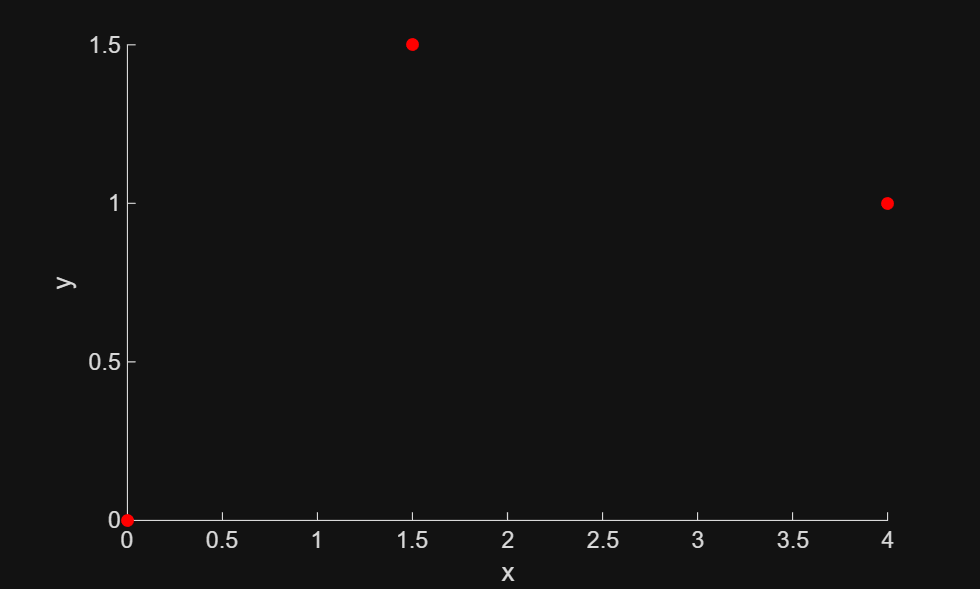

scatter(DataPoints(:,1),DataPoints(:,2), 30, 'r',"filled")
xlabel('x')
ylabel('y')

We want to find a polynomial function that passes through all these points. The most optimal function for this will be an Nth order polynomial, where N+1 is the number of points we wish to pass through; in this case, it will be a 2nd order polynomial (quadratic) since we have 3 points to pass through. The polynomial that we find should take the form: 


$$f\left(x\right)=a_0 +a_1 x+a_2 x^2 +\;\ldotp \ldotp \ldotp \;a_N x^N$$


Where N is the order of the polynomial and 1 less than the number of points we are trying to fit and each a is a coefficient.

The first step to fit the polynomial is to write the polynomial at each of the N+1 points:


$$f\left(x_1 \right)=a_0 +a_1 x_1 +a_2 {x_1 }^2 +\;\ldotp \ldotp \ldotp \;a_N {x_1 }^N$$



$$f\left(x_2 \right)=a_0 +a_1 x_2 +a_2 {x_2 }^2 +\;\ldotp \ldotp \ldotp \;a_N {x_2 }^N$$



$$f\left(x_3 \right)=a_0 +a_1 x_3 +a_2 {x_3 }^2 +\;\ldotp \ldotp \ldotp \;a_N {x_3 }^N$$


We can represent this in MATLAB through the use of matrices and vectors


$$\left\lbrack \begin{array}{c}
f\left(x_1 \right)\\
f\left(x_2 \right)\\
f\left(x_3 \right)\\
\ldotp \ldotp \ldotp \\
f\left(x_{N+1} \right)
\end{array}\right\rbrack =\left\lbrack \begin{array}{ccccc}
1 & x_1  & x_1^2  &  & x_1^N \\
1 & x_2  & x_2^2  & \ldotp \ldotp \ldotp  & x_2^N \\
1 & x_3  & x_3^2  &  & x_3^N \\
 & \ldotp \ldotp \ldotp  &  & \ldotp \ldotp \ldotp  & \\
1 & x_{N+1}  & x_{N+1}^2  &  & x_{N+1}^N 
\end{array}\right\rbrack \left\lbrack \begin{array}{c}
a_0 \\
a_1 \\
a_2 \\
\ldotp \ldotp \ldotp \\
a_N 
\end{array}\right\rbrack$$


This can be written more simply as:


$$\left\lbrack f\right\rbrack =\left\lbrack X\right\rbrack \left\lbrack a\right\rbrack$$


or


$$\left\lbrack X\right\rbrack \left\lbrack a\right\rbrack =\left\lbrack f\right\rbrack$$


We can now solve for [a] in order to find our polynomial coefficients.


$$\begin{array}{l}
\left\lbrack a\right\rbrack ={\left\lbrack X\right\rbrack }^{-1} \left\lbrack f\right\rbrack \\
\left\lbrack a\right\rbrack =\left\lbrack \begin{array}{c}
a_0 \\
a_1 \\
a_2 \\
\ldotp \ldotp \ldotp \\
a_N 
\end{array}\right\rbrack 
\end{array}$$


Let's do that for our example data:

x_Coords = DataPoints(:,1);
f = DataPoints(:,2)

f =          0
    1.5000
    1.0000



X = [1, x_Coords(1), x_Coords(1)^2;
     1, x_Coords(2), x_Coords(2)^2;
     1, x_Coords(3), x_Coords(3)^2]

X =     1.0000         0         0
    1.0000    1.5000    2.2500
    1.0000    4.0000   16.0000


a = X\f

a =          0
    1.4500
   -0.3000


Once we have our a coefficients, we just write the polynomial in the form we determined earlier and we have our function! 


$$f\left(x\right)=a_0 +a_1 x+a_2 x^2 +\;\ldotp \ldotp \ldotp \;a_N x^N$$


ApproxFunc = @(x) 0 + 1.45*x - .3*x^2;
disp('f(x) = 0 + 1.45x - .3x^2')

f(x) = 0 + 1.45x - .3x^2


% We can then plot this against our data to verify that everything fits
% correctly.
figure()
hold on
fplot(ApproxFunc,[0,4])

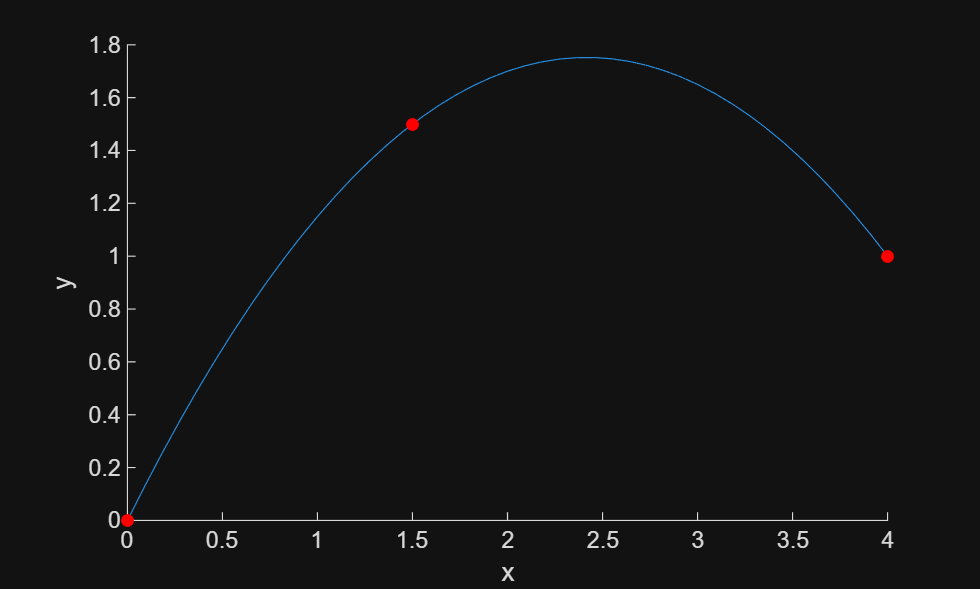

scatter(DataPoints(:,1),DataPoints(:,2), 30, 'r',"filled")
hold off
xlabel('x')
ylabel('y')

% Fit looks Good!